Highly-simplified program for simulating the epidemic in New York City from 2/29/2020 to 5/31/2020.

- S = Susceptible

- I = Infected

- R = Recovered

- L = Lost

- LPD = Lost Per Day

All times measured in days.

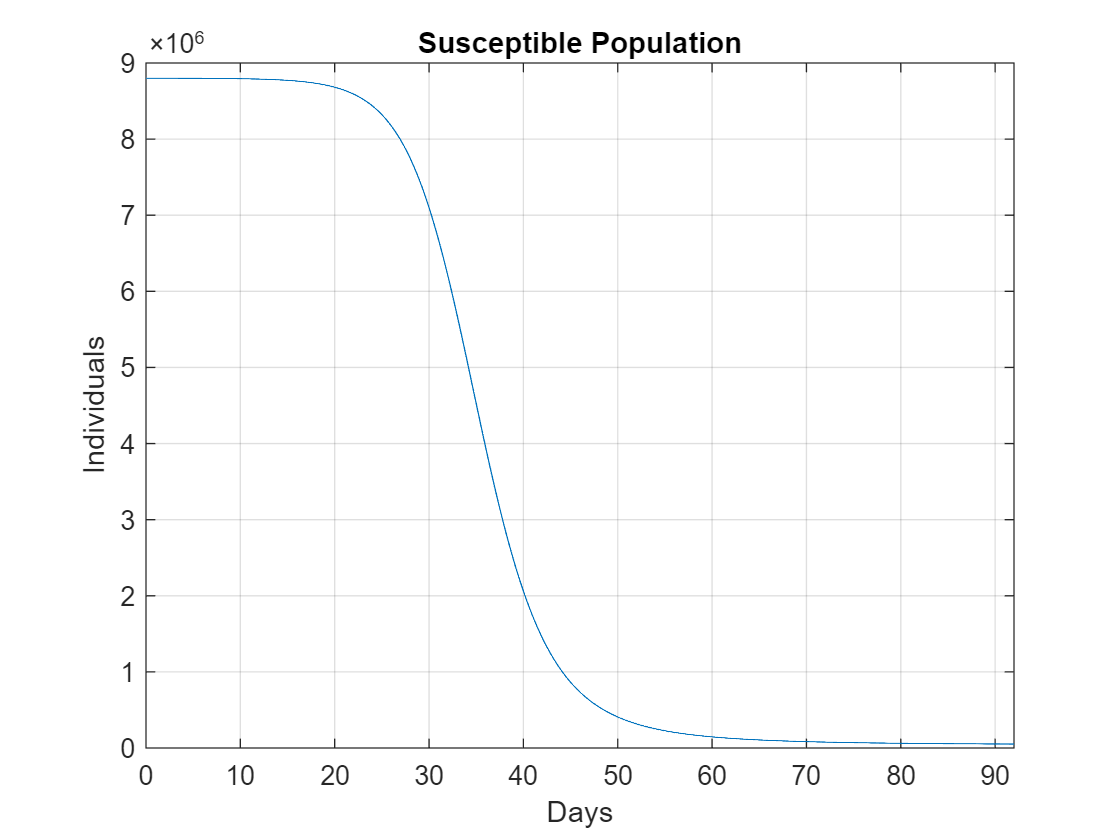

clear;

dt = 1e-3; % timestep
tMax = 92; % simulation time
t = 0:dt:tMax; % time vector

% array preallocation
S = zeros(1,tMax/dt);
I = zeros(1,tMax/dt);
R = zeros(1,tMax/dt);
dSodt = zeros(1,tMax/dt);
dRodt = zeros(1,tMax/dt);
dIodt = zeros(1,tMax/dt);
LPD = zeros(1,tMax/dt);

r = 4.05e-8; % transmission rate
a = 6.7e-2; % recovery rate
b = 2.6e-3*a; % mortality rate

S(1) = 8.8e6; % initial susceptible population
I(1) = 300; % initial infected population
R(1) = 0; % initial recovered population
for i = 1:tMax/dt
    dSodt(i+1) = -r*S(i)*I(i);
    S(i+1) = S(i)+dSodt(i+1)*dt;
    
    dRodt(i+1) = a*I(i);
    R(i+1) = R(i)+dRodt(i+1)*dt;
    
    dIodt(i+1) = -dSodt(i+1)-dRodt(i+1)-b*I(i);
    I(i+1) = I(i)+dIodt(i+1)*dt;
end

L = S(1)+I(1)+R(1)-S-I-R;

LPD(1) = L(1);
for i = 1:tMax/dt
    LPD(i+1) = (L(i+1)-L(i))/dt;
end

actualT = 0:92;
actualLPD = [0,0,0,0,0,0,0,0,0,0,0,0,0,0,1,1,2,4,7,11,18,25,32,44,58,75,103,134,173,216,261,313,371,434,492,545,602,658,707,738,750,758,761,760,754,730,700,670,635,605,568,526,493,469,449,434,407,380,360,337,320,297,280,266,253,236,223,209,196,182,166,153,143,133,121,110,103,102,98,90,85,84,79,76,71,66,63,60,56,54,51,50,48];

plot(t,S);
title('Susceptible Population');
ylabel('Individuals');
xlabel('Days');
xlim tight;
grid on;

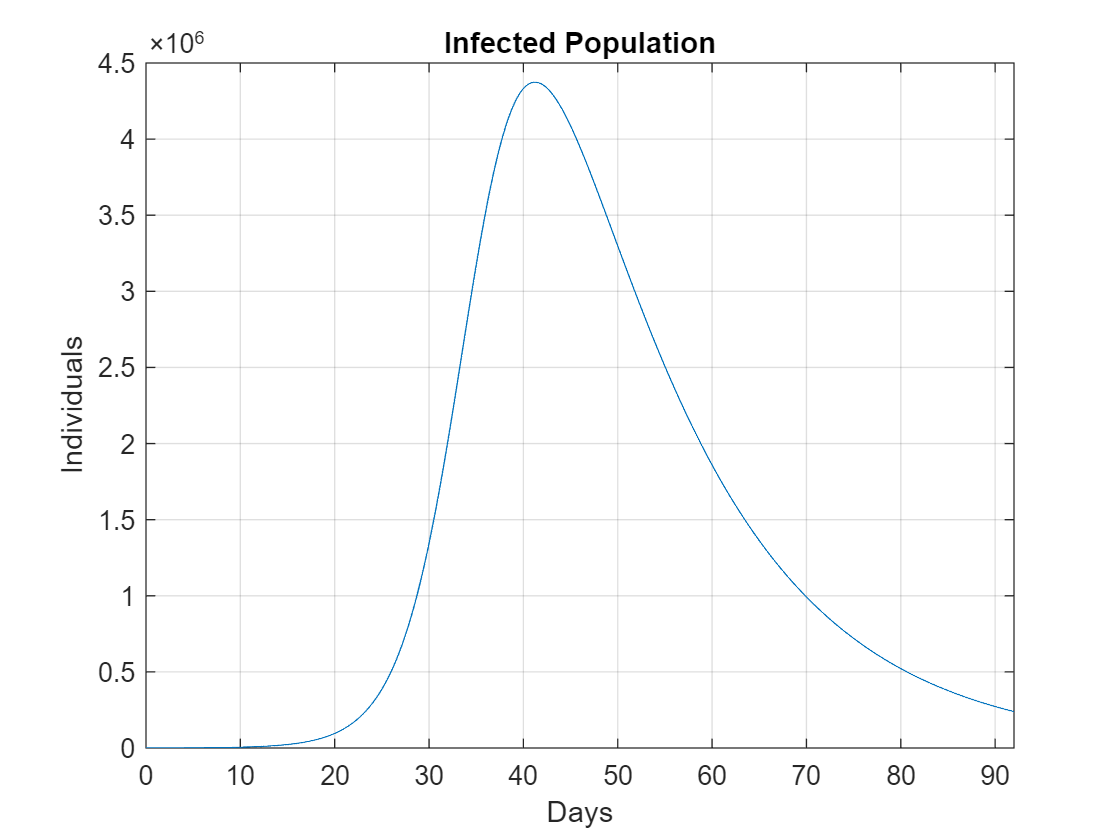

plot(t,I);
title('Infected Population');
ylabel('Individuals');
xlabel('Days');
xlim tight;
grid on;

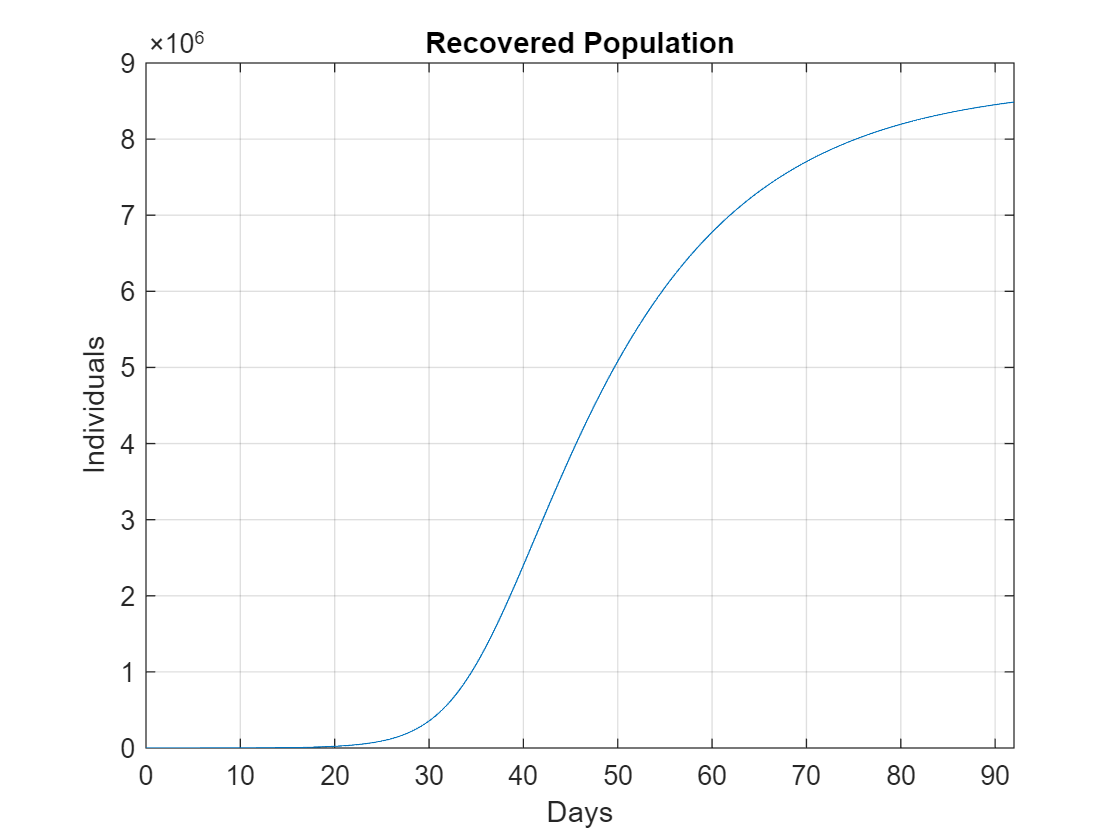

plot(t,R);
title('Recovered Population');
ylabel('Individuals');
xlabel('Days');
xlim tight;
grid on;

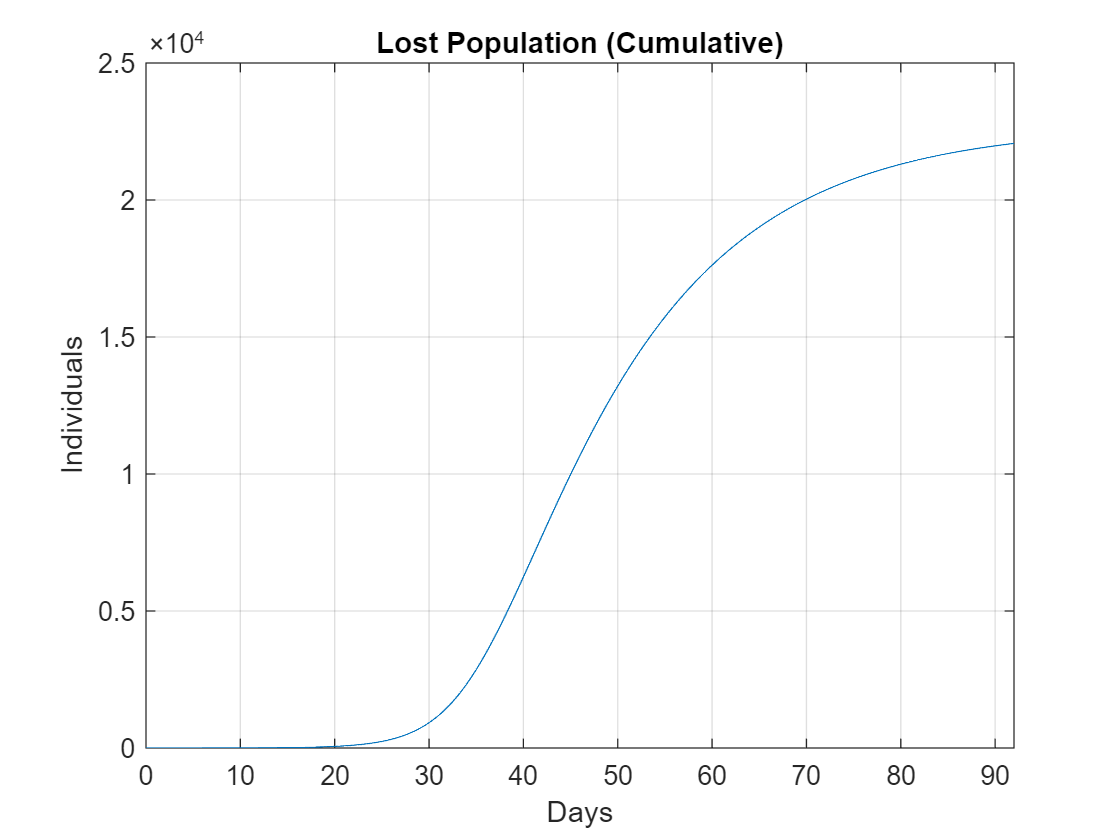

plot(t,L);
title('Lost Population (Cumulative)');
ylabel('Individuals');
xlabel('Days');
xlim tight;
grid on;

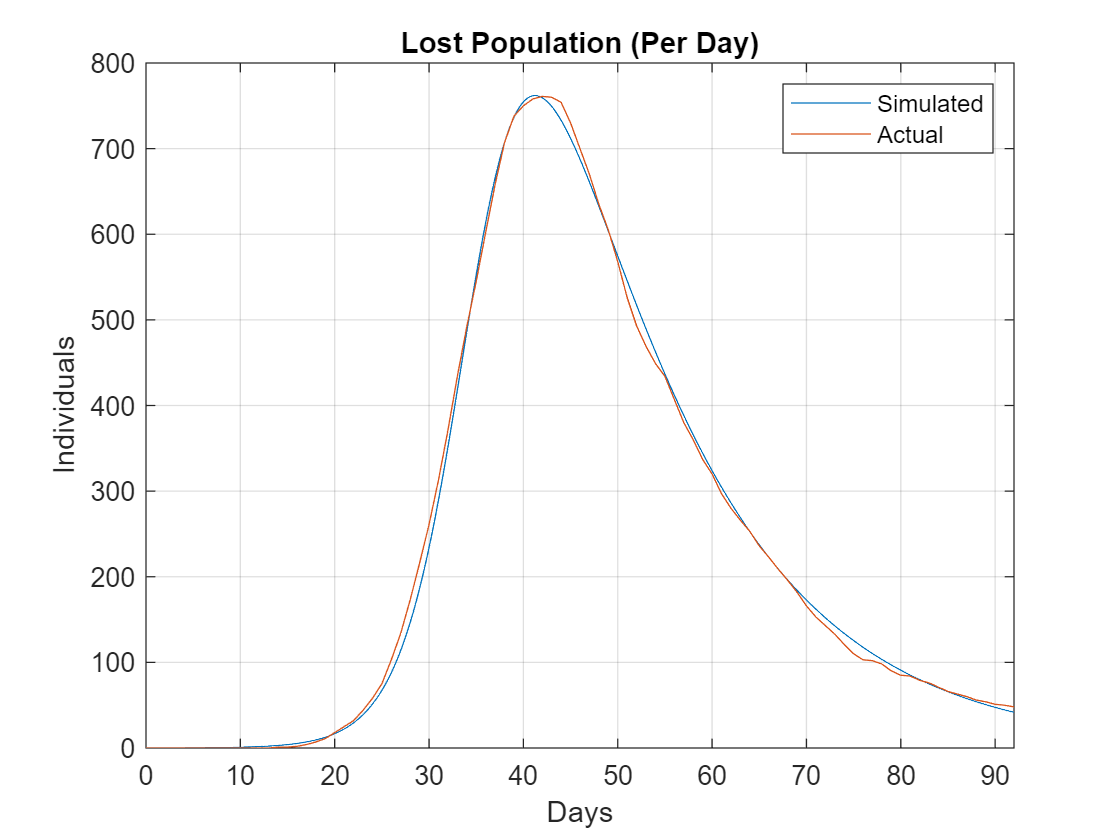

plot(t,LPD);
hold on;
plot(actualT,actualLPD);
hold off;
legend('Simulated','Actual');
title('Lost Population (Per Day)');
ylabel('Individuals');
xlabel('Days');
xlim tight;
grid on;